# Opgave 1: Gram-Schmidt

% Oefening 3
m = 200;
n = 60;

B = randn(m,n);
[Q,~] = qr(B,0);

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V

A =    -0.0282   -0.0451   -0.0401   -0.0409   -0.0248   -0.0242   -0.0268   -0.0282   -0.0283   -0.0281   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282   -0.0282
    0.0663    0.0407    0.0817    0.0801    0.0692    0.0675    0.0686    0.0662    0.0662    0.0662    0.0664    0.0664    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0.0663    0


% Oefening 4
e1 = zeros(n, 1);
e2 = zeros(n, 1);

[Q1,~] = klGS(A)

Q1 =    -0.0282   -0.0337   -0.0477   -0.1015    0.0539    0.1268    0.0889    0.0036   -0.0307    0.0331    0.0048   -0.0667   -0.0885    0.0490   -0.0368   -0.0755   -0.0666   -0.0078   -0.0942   -0.0441   -0.0783   -0.0303    0.0776    0.0281   -0.0686   -0.0993   -0.0252    0.0614    0.1961   -0.1309   -0.1707   -0.1639   -0.1648   -0.1643   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653   -0.1653
    0.0663   -0.0513    0.0613    0.1099    0.0457    0.0364    0.1467   -0.0183   -0.0454   -0.0492    0.0752    0.0466   -0.0400   -0.0820   -0.0096   -0.0223    0.0170    0.0312    0.0801    0.0404   -0.0145   -0.1324    0.0622   -0.0892    0.0484   -0.0778   -0.0654    0.0651    0.0528    0.0522    0.0841    0.0779    0.0763    0.0768    0.0769    0.0766    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    0.0767    

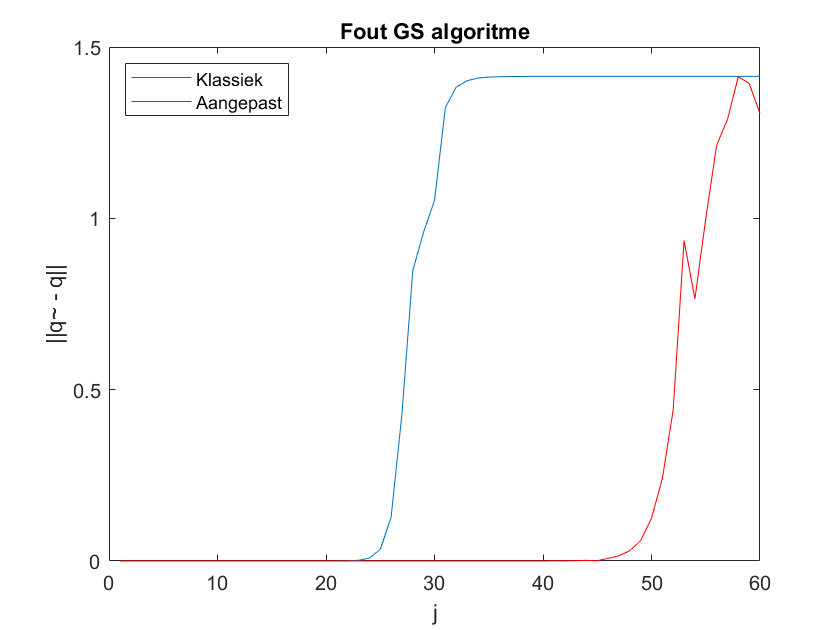

[Q2,~] = modGS(A);

for j = 1:n
    e1(j, 1) = norm(Q1(:,j)-Q(:,j));
    e2(j, 1) = norm(Q2(:,j)-Q(:,j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q||')
legend('Klassiek','Aangepast','Location','northwest')

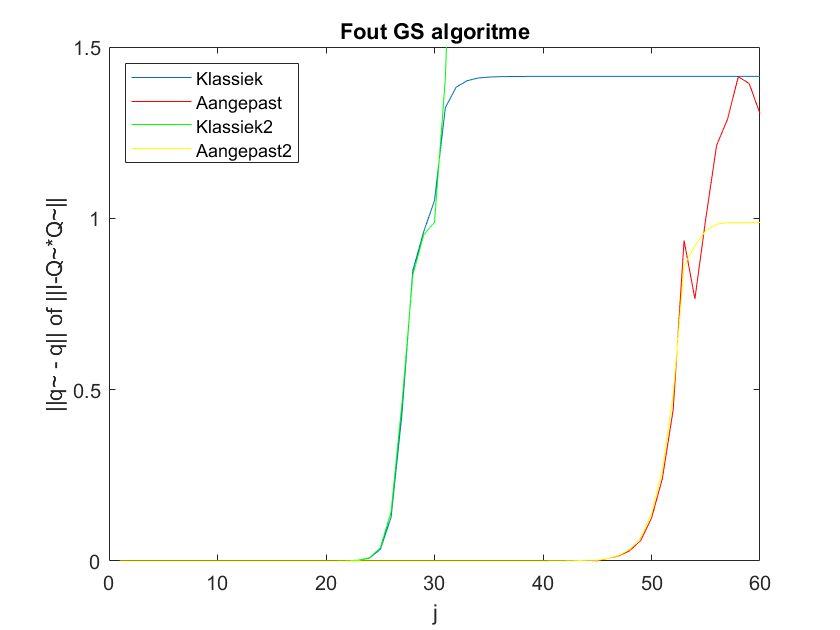


% Oefening 8
orth1 = zeros(n, 1);
orth2 = zeros(n, 1);

for j = 1:n
    orth1(j, 1) = norm(eye(j) - Q1(:,1:j)'*Q1(:,1:j));
    orth2(j, 1) = norm(eye(j) - Q2(:,1:j)'*Q2(:,1:j));
end

plot(e1)
hold on
plot(e2,'Color','r')
hold on
plot(orth1, 'Color', 'g')
hold on
plot(orth2,'Color','y')
hold off
title("Fout GS algoritme")
xlabel('j')
ylabel('||q~ - q|| of ||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Klassiek2', 'Aangepast2', 'Location','northwest')
axis([0 60 0 1.5])

% Oefening 5
m = 200;
n = 3;

B = randn(m,n);
[Q,~] = qr(B,0); 

D = eye(n,n);
for i = 1:n
    D(:,i) = D(:,i) * 2^(1-i);
end

V = eye(n,n);
V(1,:) = 1;

A = Q*D*V 

A =    -0.0985   -0.1597   -0.1062
    0.0618    0.0350    0.0608
   -0.0673   -0.0443   -0.0857
   -0.0665   -0.0891   -0.0373
   -0.0913   -0.0729   -0.0981
    0.0012    0.0186    0.0225
    0.0615    0.0749    0.0834
   -0.0016    0.0036   -0.0013
   -0.0419   -0.0110   -0.0321
    0.1782    0.1732    0.1694


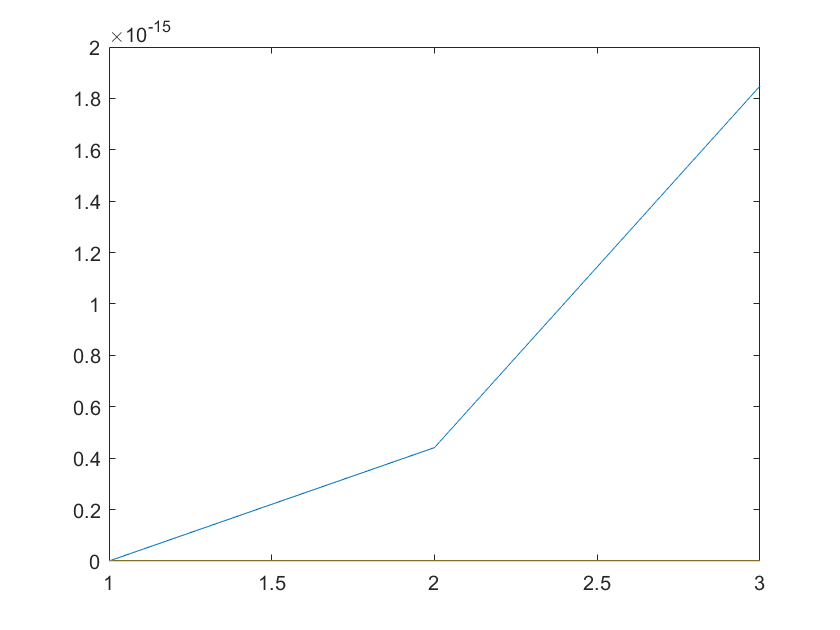


e1 = zeros(n);
[Q1,~] = klGS(A);
for j = 1:n
    e1(j) = norm(Q1(:,j)-Q(:,j));
end
plot(e1)

% Oefening 9
m = 200;
n = 50;
k = 1:50;

B = randn(m,n);
[Q,~] = qr(B,0);

[V,~] = qr(rand(n));
V = 10*rand*V;

D = zeros(n);
for i = k
    D(:,:,i) = diag(2.^linspace(0,i,n));
end
D;

A = zeros(m, n);
for i = k
    A(:,:,i) = Q*D(:,:,i)*V;
end
A;

K = zeros(length(k), 1);
for i = k
    K(i) = norm(A(:,:,i)) * norm(pinv(A(:,:,i)));
end
K

K = 	1.0e+13 *

    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


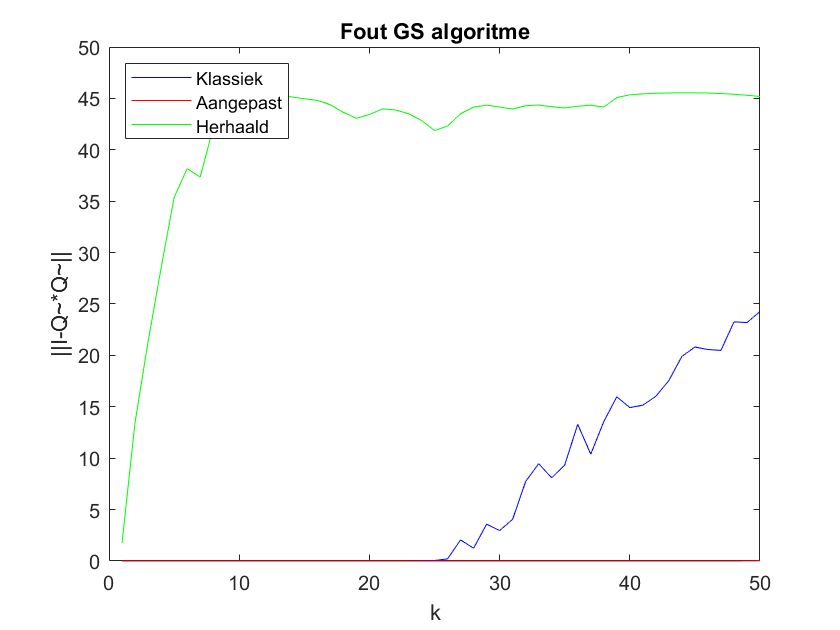


% Oefening 10
Q1 = zeros(m, n);
for i = k
    [Q1(:,:,i),~] = klGS(A(:,:,i));
end
Q1;

Q2 = zeros(m, n);
for i = k
    [Q2(:,:,i),~] = modGS(A(:,:,i));
end
Q2;

Q3 = zeros(m, n);
for i = k
    [Q3(:,:,i),~] = herGS(A(:,:,i));
end
Q3;

orth1 = zeros(length(k), 1);
for i = k
    orth1(i) = norm(eye(n) - Q1(:,:,i)'*Q1(:,:,i));
end
orth1;

orth2 = zeros(length(k), 1);
for i = k
    orth2(i) = norm(eye(n) - Q2(:,:,i)'*Q2(:,:,i));
end
orth2;

orth3 = zeros(length(k), 1);
for i = k
    orth3(i) = norm(eye(n) - Q3(:,:,i)'*Q3(:,:,i));
end
orth3;

plot(k, orth1, 'b', k, orth2, 'r', k, orth3, 'g')
hold off
title("Fout GS algoritme")
xlabel('k')
ylabel('||I-Q~*Q~||')
legend('Klassiek','Aangepast', 'Herhaald', 'Location','northwest')

# Opgave 2: Iteratieve methoden

A = sprand(1000,1000,10);
n = length(A);
m = 100;
v = rand(n,1);

[V,H] = Arnoldi(A,v,m);

